After running: motif_summarize_cEK.mlx

## Overview of NRPSs (Fig 1)

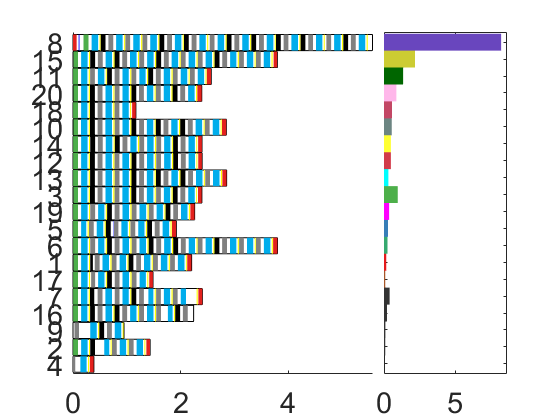

clc
% motif_summarize_cEK_20211201162950.mlx

%% actions
Fig1_overview=1;% generate overview

% basic parameters
default_fs=22;
deadclusters=find(cEK_regions.fateid==0);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% generate overall shape of all NRPSs with their length and expressions
if Fig1_overview
    firstsize=7;
    regions_list=[];
    for fateid=0:1:2 % dead, maybe, active %  % regions_list=[4,2,16,9,7,17,6,1,5,19,3,13,10,12,14,20,18,11,15,8];
        toaddr=find(cEK_regions.fateid==fateid);
        [~,order]=sort(cEK_regions.exp_relative(toaddr));
       regions_list=[regions_list, toaddr(order)'];
    end
  
    showspecificity=0;
    figure;
    
    subplot(1,10,1:firstsize);
    textposi=-1000;
    hold on;
    for r=1:length(regions_list)
        rid=regions_list(r);
        seqlen=cEK_regions.seqlen(rid);
        patch([0,1,1,0]*seqlen+1,[0,0,1,1]*0.95+r-0.5,[1,1,1]);
        % color all "domains alone this cluster"
        domains_thisregion=find(cEK_omains.isdomain==1 & cEK_omains.region_ids==rid);
        for d=1:length(domains_thisregion)
            did=domains_thisregion(d);
            dtype=cEK_omains.typeid_mat(did,1);
            seposi=cEK_omains.boarders(did,:);
            if strcmp(cEK_omains.subtypestr{did},'Condensation_Starter')
                colorcode=cEK_omains.colorcode(end,:);
            elseif ~(dtype>size(cEK_omains.colorcode,1))
                colorcode=cEK_omains.colorcode(dtype,:);
            else
                colorcode=[0,0,1];
            end
            ph=patch([seposi,fliplr(seposi)],[0,0,1,1]*0.95+r-0.5,colorcode);
            ph.LineStyle='none';
            
            % If we'd like to show the specificity
            if showspecificity && strcmp(cEK_regions.fate{rid},'Active')
                sp_id=cEK_omains.specificity_id(did);
                if ~isnan(sp_id)
                    tb=text(seposi(1)+100,r,amino_table_1_3_long{sp_id,1});
                    tb.Color=[1,1,1]*0.3;
                end
            end
            
        end%    for d=1:length(domains_thisregion)
        
        %ms=50;
        %scatter(textposi,r,ms,cEK_regions.cluster_colors(rid,:),'filled');
        
    end % for r=1:length(regions_list)
    xlim([0,max(cEK_regions.seqlen)+100])
    %xlim([2*textposi,max(cEK_regions.seqlen)+100])
    ylim([0.4 20.6])
    set(gca,'fontsize',default_fs,'ytick',1:cEK_regions.num,'yticklabel',strsplit(num2str(regions_list)));%cEK_regions.shortfolder(regions_list));
    xlabel('Sequence length (bp)')
    
    subplot(1,10,(firstsize+1):10);
    hold on;
    productstr=[]; 
    for r=1:length(regions_list)
        productstr{r}='';
        rid=regions_list(r);
        barlen=cEK_regions.exp_relative(rid)*100;
        if 1%rid==8 % NPRS8
            colorcode=cEK_regions.cluster_colors(rid,:);
        elseif cEK_regions.fateid(rid)==2 % active
            colorcode=[0,1,0];
        elseif cEK_regions.fateid(rid)==1 % looks good
            colorcode=[0,0,1];
        else
            colorcode=[0,0,0];
        end
colorcode=min(1,max(0,colorcode));
        ph=patch([0,1,1,0]*barlen,[0,0,1,1]*1+r-0.5,colorcode);
        ph.LineStyle='none';
    end
    xlim([0 max(cEK_regions.exp_relative)*105])
    xlabel('Expression %')
    ylim([0.4 20.6]);
    set(gca,'fontsize',default_fs,'ytick',1:cEK_regions.num,'YTickLabel',productstr);
    box on
end

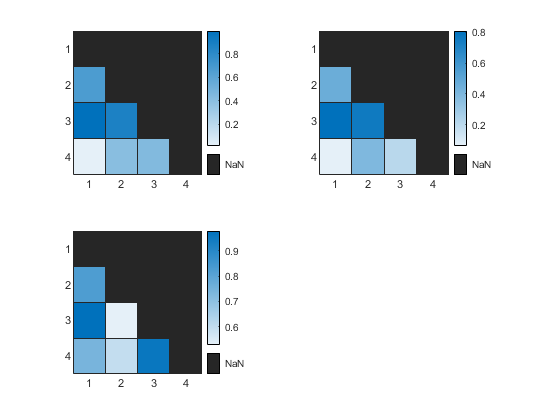

%% matrix used for demonstrating the "matrix correlation"
rng(94433437)%2855486
testv=[];
testv(1,:)=rand(1,6);
testv(2,:)=testv(1,:)+0.5*(rand(size(testv(1,:)))-0.5);
c1=corrcoef(testv(1,:),testv(2,:));
testv(3,:)=rand(1,6);
c2=corrcoef(testv(1,:),testv(3,:));
figure;
for i=1:3
    subplot(2,2,i)
    tempm=squareform(testv(i,:));
    for j=1:size(tempm,1)
        tempm(j,j:end)=nan;
    end
    heatmap(tempm); % 'Colormap','jet'
    
end

[min(c1(:)),min(c2(:))]

ans =     0.9563    0.1227


## Distrupted Phylogeny (Fig 1)

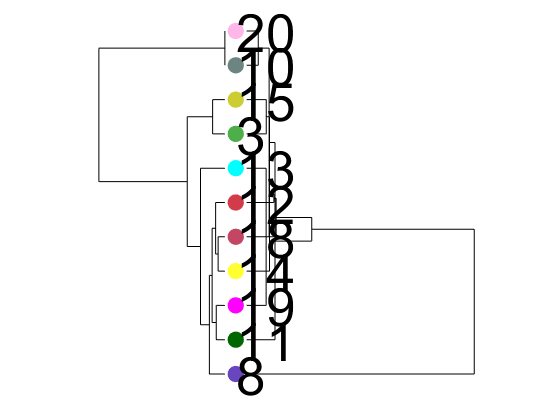

goodcEKrlist=([find(cEK_regions.fateid>1);3;19]);% alive


% Tree generated by head C and tails  T
treemethod='average';
ntoraa=2;

% get the head distance
diststruct_C=cEK_omains.diststruct_bytype{cEK_omains.unitype_mat(:,1)==Ctype & cEK_omains.unitype_mat(:,2)==0};
did_2_loc=diststruct_C.did_2_loc;
startC_olist=[];
nodenames=[];
for c=1:cEK_regions.num
    if ismember(c,goodcEKrlist)
        Cs_thiscluster=intersect(find(cEK_omains.region_ids==c),diststruct_C.olist);
        startC_olist(end+1)=min(Cs_thiscluster);
        nodenames{end+1}=num2str(c);
    end
end
aadistm_startC=diststruct_C.distm_ntaa{ntoraa}(did_2_loc(startC_olist),did_2_loc(startC_olist));
linkage_startC=linkage(aadistm_startC, treemethod);
optorder_startC=optimalleaforder(linkage_startC,aadistm_startC);


% get the tail distance
%diststruct_T=cEK_omains.diststruct_bytype{cEK_omains.unitype_mat(:,1)==Ttype & cEK_omains.unitype_mat(:,2)==0};
diststruct_TE=cEK_omains.diststruct_bytype{cEK_omains.unitype_mat(:,1)==TEtype & cEK_omains.unitype_mat(:,2)==0};
did_2_loc=diststruct_TE.did_2_loc;
stopT_olist=[];
for c=1:cEK_regions.num
    if ismember(c,goodcEKrlist)
        TEs_thiscluster=intersect(find(cEK_omains.region_ids==c),diststruct_TE.olist);
        stopT_olist(end+1)=min(TEs_thiscluster);
    end
end
aadistm_stopT=diststruct_TE.distm_ntaa{ntoraa}(did_2_loc(stopT_olist),did_2_loc(stopT_olist));
linkage_stopT=linkage(aadistm_stopT, treemethod);


figure;
treevisuapara=[];
treevisuapara.start_x_y=[-0.1,0];
treevisuapara.linewidth=0.5;
treevisuapara.linewidth=0.5;
treevisuapara.treetowards='Right';
ZL_PlotTree(linkage_startC,optorder_startC,[],treevisuapara);
axis off

hold on;
treevisuapara.start_x_y=[0.1,0];
treevisuapara.treetowards='Left';
ZL_PlotTree(linkage_stopT,optorder_startC,[],treevisuapara);

smsize=150;
txsize=40;
for i=1:length(startC_olist)
    oid=startC_olist(optorder_startC(i));
    rid=cEK_omains.region_ids(oid);
    scatter(0,i,smsize,cEK_regions.cluster_colors(rid,:),'filled')
    text(0,i,num2str(rid),'Fontsize',txsize, 'HorizontalAlignment','left','VerticalAlignment','middle')
end

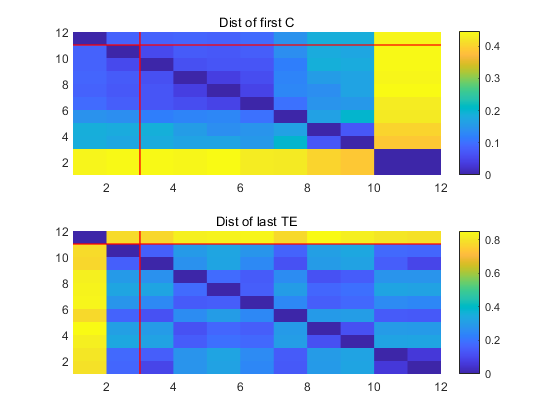


figure;
subplot(2,1,1)
Easypcolor_flip_LZY(aadistm_startC(optorder_startC,optorder_startC),'u',nodenames(optorder_startC));
ch=colorbar;
title('Dist of first C')
subplot(2,1,2)
Easypcolor_flip_LZY(aadistm_stopT(optorder_startC,optorder_startC),'u',nodenames(optorder_startC));
colorbar
title('Dist of last TE')



figure;
ms=30;
x=squareform(aadistm_startC(optorder_startC,optorder_startC));
y=squareform(aadistm_stopT(optorder_startC,optorder_startC));
hold on;
for i=1:length(startC_olist)
    for j=1:(i-1)
        r_i=cEK_omains.region_ids(startC_olist(i));
        r_j=cEK_omains.region_ids(startC_olist(j));
        if cEK_omains.region_ids(startC_olist(i))~=cEK_omains.region_ids(stopT_olist(i))
            error('wtf')
        else
            v1=aadistm_startC(i,j);
            v2=aadistm_stopT(i,j);
            sh=scatter(v1,v2,ms);
            sh.MarkerFaceColor =cEK_regions.cluster_colors(r_i,:);
            sh.MarkerEdgeColor=cEK_regions.cluster_colors(r_j,:);
        end
    end
end

xlabel('Cs')
ylabel('TE')
box on 
corm=corrcoef(x,y)

corm =     1.0000   -0.0650
   -0.0650    1.0000


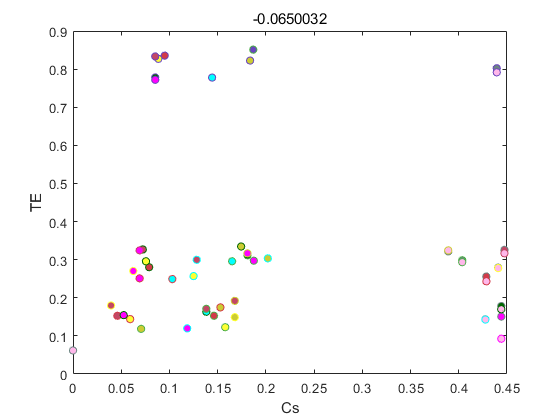

title(corm(1,2))

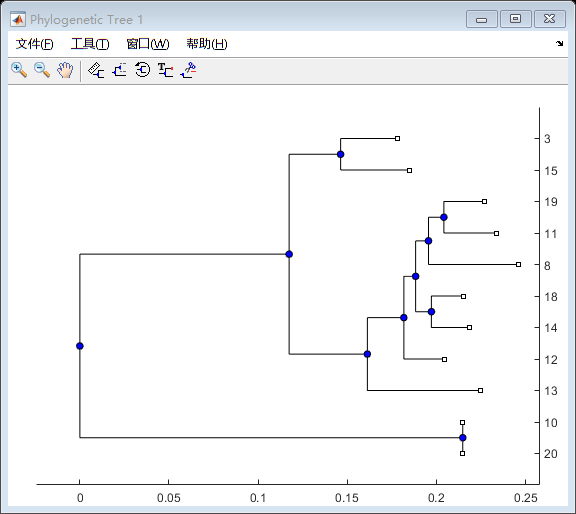



Csphytree = seqneighjoin(aadistm_startC,'equivar',strsplit(num2str(cEK_omains.region_ids(startC_olist)')));
view(Csphytree)

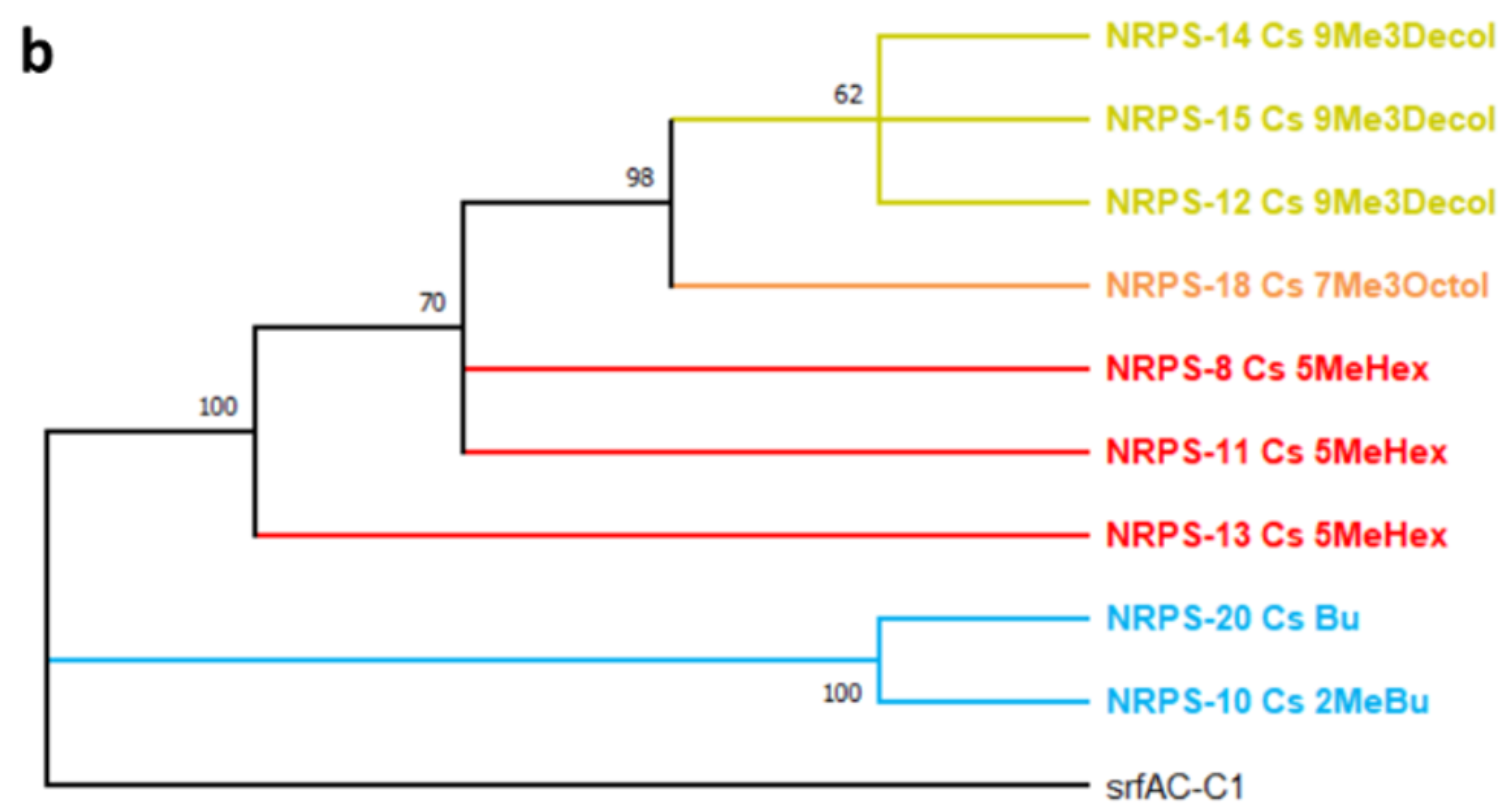

% load the faty acid data for start
nastr='na';
Cs_facid=[];
for i=1:20
    Cs_facid{i,1}=nastr;
end

Cs_facid{12}='9Me3Decol';
Cs_facid{14}='9Me3Decol';
Cs_facid{15}='9Me3Decol';
Cs_facid{18}='7Me3Decol';

Cs_facid{8}='5MeHex';
Cs_facid{11}='5MeHex';
Cs_facid{13}='5MeHex';
Cs_facid{19}='na';%5MeHex

Cs_facid{10}='Bu';
Cs_facid{20}='Bu';
if 0
    Cs_facid{12}='Me';
    Cs_facid{14}='Me';
    Cs_facid{15}='Me';
    Cs_facid{18}='Me';
    
    Cs_facid{8}='Me';
    Cs_facid{11}='Me';
    Cs_facid{13}='Me';
    Cs_facid{19}='na';%5MeHex
    
    Cs_facid{10}='Bu';
    Cs_facid{20}='Bu';
end



% load the TE 

TE_cyctype=[];
for i=1:20
    TE_cyctype{i,1}=nastr;
    TE_cyctype{i,2}=nastr;
end

TE_cyctype{12,1}='FA';TE_cyctype{12,2}='6Y';
TE_cyctype{14,1}='FA';TE_cyctype{14,2}='6W';
TE_cyctype{15,1}='FA';TE_cyctype{15,2}='10P';
TE_cyctype{18,1}='FA';TE_cyctype{18,2}='3R';

TE_cyctype{8,1}='aa';TE_cyctype{8,2}='T-13V';

TE_cyctype{11,1}='aa';TE_cyctype{11,2}='S-7G';
TE_cyctype{13,1}='aa';TE_cyctype{13,2}='T-7V';
TE_cyctype{19,1}=nastr;TE_cyctype{19,2}='?';

TE_cyctype{10,1}='aa';TE_cyctype{10,2}='T-7S';
TE_cyctype{20,1}='aa';TE_cyctype{20,2}='T-6I';


Then, get the tot_MSA for Cs and TE

ans =     11    11


ans =     11     1


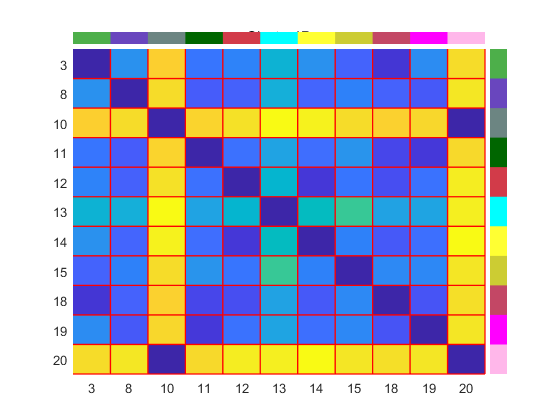

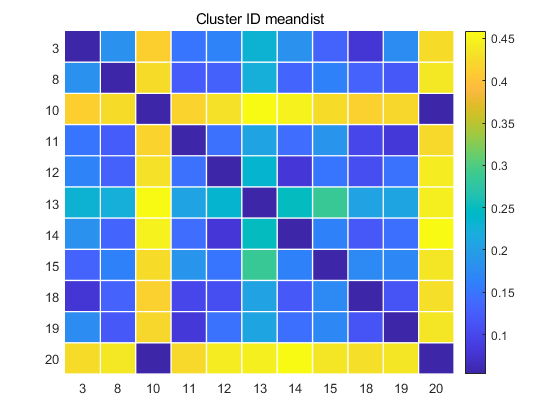

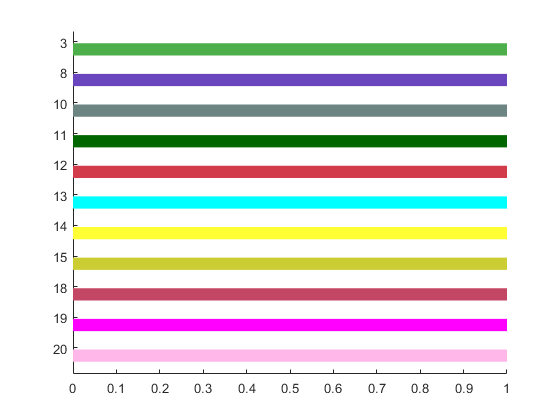

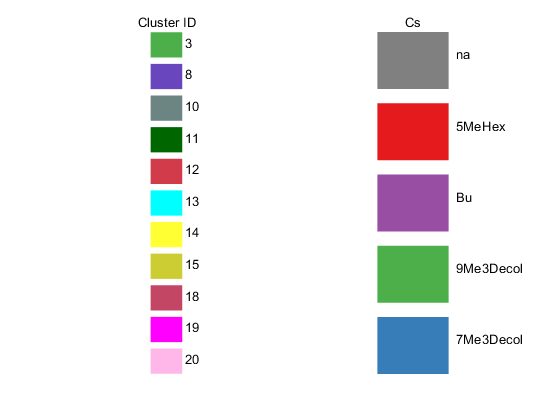

ans =     11    11


ans =     11     1


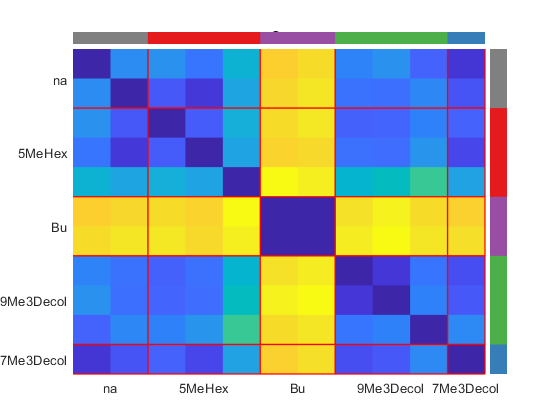

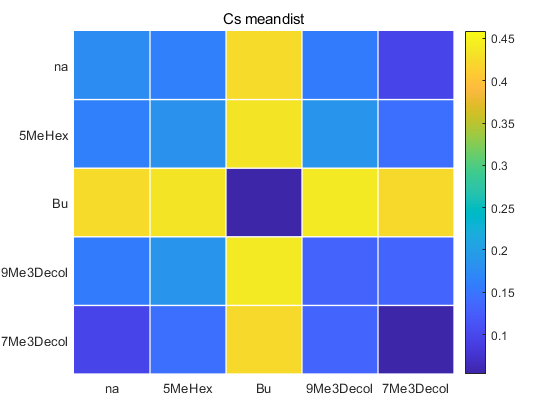

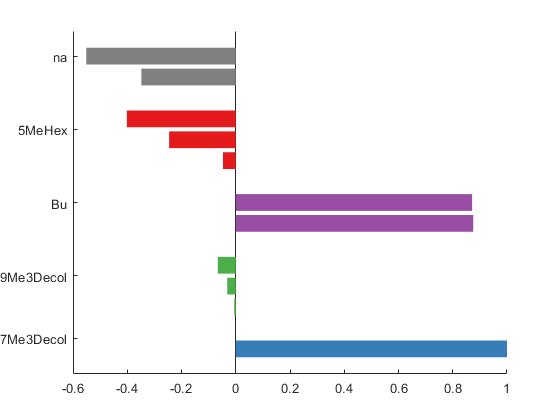

% Cs for alive ones, from start of C1 to A1
%goodcEKrlist=find(cEK_regions.fateid>1);% active: use this, get similar result as the previous figure


%%%
dtype=Ctype;
progresslist=(1:0.5:10)';
Cs_combined_types=[[dtype*ones(size(progresslist)),progresslist];
    Atype,0.5;
    Atype,1];

mlist_firstmotif=find(ismember(motif_struct.region_id,goodcEKrlist) & ismember(motif_struct.motifid_mat_list,Cs_combined_types(1,:),'rows') & cEK_omains.moduleid(motif_struct.omains_id)==1);
loc_firstmotif=1;
Cs_motif_mats=zeros(length(mlist_firstmotif),size(Cs_combined_types,1)); % all motifs related to this one
badmlist=[];
for i=1:length(mlist_firstmotif)
    for j=1:size(Cs_combined_types,1)
        shouldbe_mid = mlist_firstmotif(i)+j-loc_firstmotif;
        if ismember(motif_struct.motifid_mat_list(shouldbe_mid,:),Cs_combined_types(j,:),'rows')
            Cs_motif_mats(i,j)=shouldbe_mid;
        else
            error('w')
            badmlist(end+1)=i;
        end
    end
end %for i=1:length(m_list)
Cs_motif_mats(badmlist,:)=[];

% get specificity
second_olist=motif_struct.omains_id(Cs_motif_mats(:,2));
[Cs_unifstr,~,mat_specificity]=unique(Cs_facid(cEK_omains.region_ids(second_olist)));
naloc=find(strcmp(Cs_unifstr,nastr));
if ~isempty(naloc); mat_specificity(mat_specificity==naloc)=nan;end

% get the total msa
lastlen=0;
Cs_motifid_mdist_mul_gap=[]; % alone the whole
Cs_tot_msa=[];
dist_Cs=zeros(length(second_olist));
for m=1:size(Cs_motif_mats,2)
    m_mat=Cs_motif_mats(:,m);
    
    thism_type=Cs_combined_types(m,:);
    
    motifloc=find(ismember(motif_struct.uni_motifids,thism_type,'rows'));
    diststruct_mlist=motif_struct.motif_diststruct{motifloc}.mlist;
    diststruct_olist=motif_struct.motif_diststruct{motifloc}.olist;
    diststruct_distm=squareform(motif_struct.motif_diststruct{motifloc}.distline);
    diststruct_msa=motif_struct.motif_diststruct{motifloc}.msa;
    
    
     % only extract these in "good regions"
    diststruct_list_2_use=nan*zeros(size(m_mat));
    for i=1:length(diststruct_list_2_use) % hereya
        loc=find(diststruct_mlist==m_mat(i));
        if ~isempty(loc)
            diststruct_list_2_use(i)=loc;  % hereya   
        else
            error('seq not here');
        end
        diststruct_list_2_use(i)=loc;
    end % hereya
    
    
    % identity and length
    meanlen_toadd=mean(motif_struct.seqlen_aa(diststruct_mlist(diststruct_list_2_use)));
    
    
    % add to the "distance"
    for i=1:size(m_mat,1)
        loc_i_indist=find(m_mat(i)==diststruct_mlist);
        for j=1:(i-1)
            loc_j_indist=find(m_mat(j)==diststruct_mlist);
            if ~isempty(loc_i_indist) && ~isempty(loc_j_indist)
                    if isnan(diststruct_distm(loc_i_indist,loc_j_indist))
                        toaddv=0;
                    else
                        toaddv=diststruct_distm(loc_i_indist,loc_j_indist);
                    end
            end
            dist_Cs(i,j)=dist_Cs(i,j)+meanlen_toadd*toaddv;
            dist_Cs(j,i)=dist_Cs(i,j);
        end
    end
    
   
   
    %%%%% obtain mutual informations
    %loc_in_mmat=0*diststruct_list_2_use; % hereya
    %for b=1:length(loc_in_mmat)
    %    loc_in_mmat(b)=find(m_mat==diststruct_mlist(diststruct_list_2_use(b)));
    %end
    
    % calculate mutual information
    m_specificity=mat_specificity;%(loc_in_mmat);% hereya
    msa=diststruct_msa(diststruct_list_2_use,:);% hereya
    nanpercent=sum(msa=='-',1)/size(msa,1);
    
    %[value,order]=sort(nanpercent);nanthresh=max(0.5,value(ceil(meanlen_toadd)));
    %msa=msa(:,nanpercent<nanthresh);
    
    msa_num=aa2int(msa);
    msa_num(msa=='-'|msa=='*')=nan;
    
    %  fprintf('%f\t%f\t%f\n',nanthresh,size(msa,2),meanlen_toadd)
    
    mulinfor_list=zeros(1,size(msa_num,2));
    for s=1:size(msa_num,2)
        nonzerolist=find(m_specificity>0);
        
        [H1,H2,CH1_given2,CH2_given1,mulin]=ZL_Mulinfor_int(msa_num(nonzerolist,s),m_specificity(nonzerolist));
        mulinfor_list(s)=mulin;
    end
    
    [condiH_eachsite,totalH,meandist_eachsite]=ZL_MotifbyConveration(msa,'aa',[],0);
    
    
    addeddata=[m*ones(size(mulinfor_list));
        meandist_eachsite;
        mulinfor_list;
        nanpercent];
    Cs_motifid_mdist_mul_gap=[Cs_motifid_mdist_mul_gap,addeddata];
    
    
    Cs_tot_msa=[Cs_tot_msa,msa];
    
    
    lastlen=lastlen+meanlen_toadd;
end

dist_Cs=dist_Cs/lastlen;


gap_thresh=0.5;
column_to_keep=find(Cs_motifid_mdist_mul_gap(end,:)<gap_thresh);

% hirachical clusering and distance heatmap
% group by specificity
rfromsecond_olist=cEK_omains.region_ids(second_olist);
g1=[];
[g1.id_2_name,~,g1.ids]=unique(Cs_facid(rfromsecond_olist));%;cEK_omains.specificity_id(second_olist);
g1.id_2_color=cbrewer('qual','Set1',sum(~strcmp(g1.id_2_name,nastr)));
g1.id_2_color(find(strcmp(g1.id_2_name,nastr)),:)=0.5*[1,1,1];
g1.name='Cs';

g2=[];
g2.ids=cEK_omains.region_ids(second_olist);
g2.id_2_name=strsplit(num2str(1:cEK_regions.num));
g2.id_2_color=cEK_regions.cluster_colors;
g2.name='Cluster ID';



groups={g2,g1};
figure;
[fhandles,optleafOrder,ai_bi_index]=DistMatrix_Analysis_HRL(dist_Cs,{'phytree_average','Silhouette'},groups);

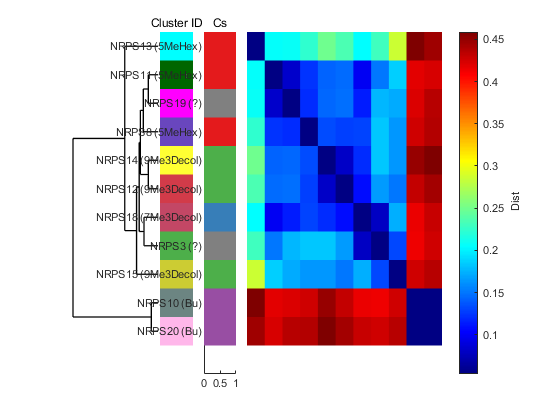

%[fhandles,optleafOrder,ai_bi_index]=DistMatrix_Analysis_HRL(aadistm_startC,{'phytree_complete','Silhouette'},groups);


figure(fhandles(1))
axis on
set(gca,'ytick',0.5+(1:length(second_olist)));

ylabelstrs=[];
for i=1:length(optleafOrder)
    oid=second_olist(optleafOrder(i));
    rid=cEK_omains.region_ids(oid);
    
    actuals=Cs_facid{rid};
    if strcmp(actuals,'na')
        actuals='?';
    end
    sstr=sprintf('NRPS%d (%s)',rid, actuals);
    ylabelstrs{length(optleafOrder)+1-i}=sstr;
end
set(gca,'yticklabel',ylabelstrs);
colormap('jet')




%
figure;
hold on;
% assign color
mulinfor_eachsite=Cs_motifid_mdist_mul_gap(3,column_to_keep)./H2;
colortable=flipud(colormap('parula'));
colornum=size(colortable,1);
mulinfor_colorid=max(1,min(colornum,round(colornum*(mulinfor_eachsite))));

for i=1:length(column_to_keep)
    posi=column_to_keep(i);
    bh=bar(i,Cs_motifid_mdist_mul_gap(2,posi),1);
    bh.EdgeColor='none';
    bh.FaceColor=colortable(mulinfor_colorid(i),:);
end

% mark positions for motifs
for i=1:size(Cs_combined_types,1)
    mtype=Cs_combined_types(i,:);
    if abs(mtype(2)-round(mtype(2)))<0.1 && ~ismember(mtype(2),[5,6,10])
        locs=find(Cs_motifid_mdist_mul_gap(1,column_to_keep)==i);
        
        if i<20
             colorcode=cEK_omains.colorcode(Ctype,:);
             if mtype(2)>4
                 mid=mtype(2)-2;
             else
                 mid=mtype(2);
             end
            textstr=['C',num2str(mid)];
        else
         colorcode=cEK_omains.colorcode(Atype,:);  
         textstr=['A',num2str(mtype(2))];
        end
        ph=patch([locs(1),locs(end),locs(end),locs(1)],[0,0,-1,-1]*0.02,colorcode);
        ph.EdgeColor='k';
        text((locs(1)),-0.05,textstr)
        
    end
end

% locate the CA motif
CSeq_CA = seqconsensus(Cs_tot_msa(:,column_to_keep));
CAmotif='ELLETFNHTEVAYP'

CAmotif = 'ELLETFNHTEVAYP'

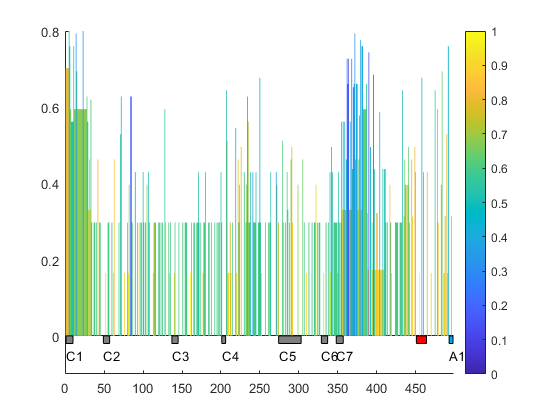

AlignStruct = localalign(CSeq_CA, CAmotif);
CAposi=AlignStruct.Start(1,1):AlignStruct.Stop(1,1);%437:450;'ELLETFNHTEVAYPRD';
hold on;
locs=CAposi;
colorcode=[1,0,0];
ph=patch([locs(1),locs(end),locs(end),locs(1)],[0,0,-1,-1]*0.02,colorcode);
ph.EdgeColor='k';


ylim([-0.1,0.8]);
set(gca,'ytick',0:0.2:1);
colorbar

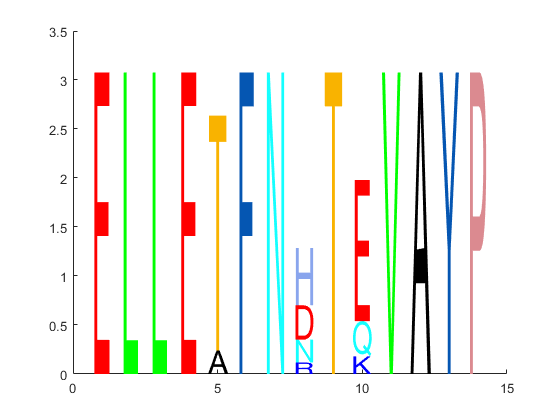

ans = 3.0760


figure;
SeqLogo_HRL((Cs_tot_msa(:,column_to_keep(CAposi))),'aa',aa_colormaping,letterclass,0)



 
%
%LHLAQQGIYFDQLLDLEDPCYNCGG, 26~% the last G: 25 in poymol
% KLSKDSFYFVL, 147~ % the last L, 136 in poymol

highinforsite=find(mulinfor_eachsite>0.8);

% 

% find the high-information site:
[~,order]=sort(mat_specificity);
Cs_tot_msa(order,column_to_keep(highinforsite))

ans = 11×8 char 数组
    'ITTEFSVA'
    'ITTEFSVA'
    'ITTEFSV-'
    'TIVEVTSV'
    'TI----SV'
    'TI----GV'
    'TITNASGV'
    'VVNMVFAG'
    'VVNMVFDG'
    'TIVEVTSV'
    'ITTEFSVA'


Cs_facid(cEK_omains.region_ids(second_olist(order)))

ans = 11×1 cell 数组
    {'5MeHex'   }
    {'5MeHex'   }
    {'5MeHex'   }
    {'7Me3Decol'}
    {'9Me3Decol'}
    {'9Me3Decol'}
    {'9Me3Decol'}
    {'Bu'       }
    {'Bu'       }
    {'na'       }
    {'na'       }


cEK_omains.region_ids(second_olist(order))

ans =      8
    11
    13
    18
    12
    14
    15
    10
    20
     3


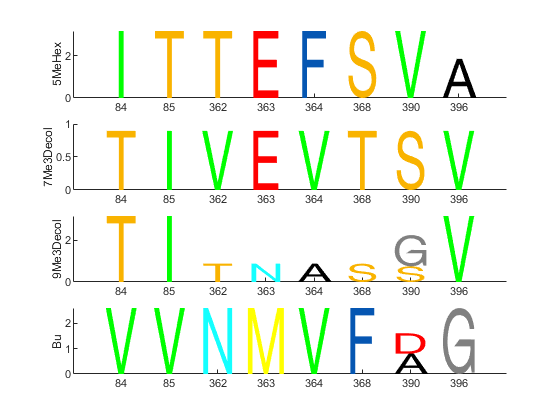


figure;
for i=1:max(mat_specificity)
    subplot(max(mat_specificity),1,i);
    thisrow=find(mat_specificity==i);
    tousestr=Cs_tot_msa(thisrow,column_to_keep(highinforsite));
    
        tousestr=[tousestr;
            tousestr;
            tousestr;
            tousestr];
    
    SeqLogo_HRL(tousestr,'aa',aa_colormaping,letterclass,0);
    set(gca,'xtick',1:length(highinforsite));
    set(gca,'xticklabel',strsplit(num2str(highinforsite)));
    ylabel(Cs_unifstr{i});
end

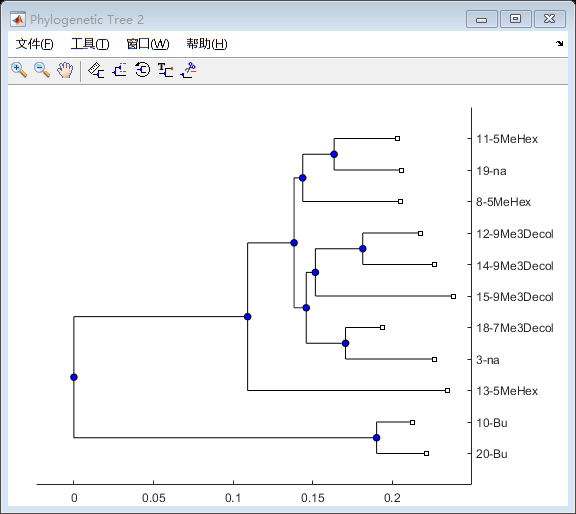


% write out the things by their 


% and how it clusters
Csnames=[];
for i=1:length(second_olist)
    cid=cEK_omains.region_ids(second_olist(i));
    Csnames{i}=[num2str(cid),'-',Cs_facid{cid}];
end
Csphytree = seqneighjoin(dist_Cs,'equivar',Csnames);
view(Csphytree)


% use a previous

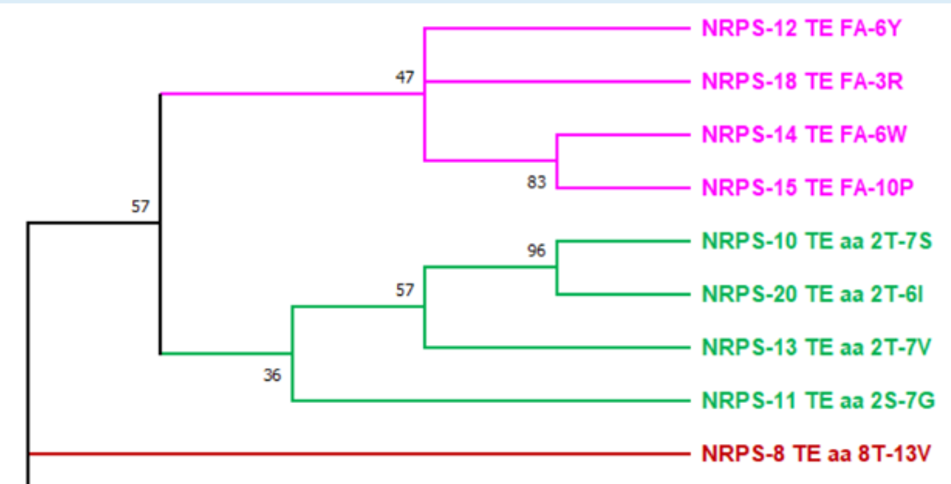

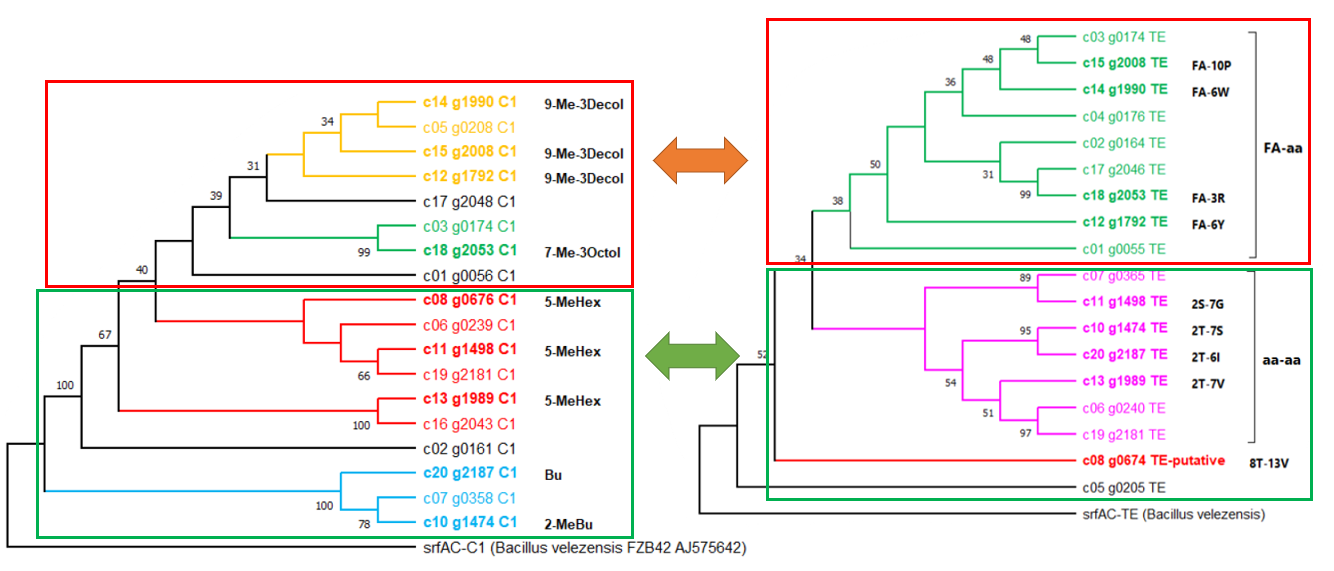

% TE, from last T1 0.5 to the end


%%%

TE_combined_types=[
    Ttype,1;
    TEtype,0.5;
    TEtype,1;
    TEtype,1.5];
list=find(motif_struct.region_id==8);addlist=[list(end-1);list(1:3)];

TE_combined_types=[Ttype,0.5
    Ttype,1;
    TEtype,0.5;
    TEtype,1;
    TEtype,1.5];
list=find(motif_struct.region_id==8);addlist=[list((end-2):(end-1));list(1:3)];



mlist_firstmotif=find(ismember(motif_struct.region_id,goodcEKrlist) & ismember(motif_struct.motifid_mat_list,TE_combined_types(1,:),'rows'));
loc_firstmotif=1;
TE_motif_mats=zeros(length(mlist_firstmotif),size(TE_combined_types,1)); % all motifs related to this one
badmlist=[];
for i=1:length(mlist_firstmotif)
    for j=1:size(TE_combined_types,1)
        shouldbe_mid = mlist_firstmotif(i)+j-loc_firstmotif;
        if ismember(motif_struct.motifid_mat_list(shouldbe_mid,:),TE_combined_types(j,:),'rows')
            TE_motif_mats(i,j)=shouldbe_mid;
        else
            badmlist(end+1)=i;
        end
    end
end %for i=1:length(m_list)
TE_motif_mats(badmlist,:)=[];


TE_combined_types

TE_combined_types =     3.0000    0.5000
    3.0000    1.0000
    5.0000    0.5000
    5.0000    1.0000
    5.0000    1.5000


motif_struct.motifid_mat_list(addlist,:)

ans =     3.0000    0.5000
    3.0000    1.0000
    5.0000    0.5000
    5.0000    1.0000
    5.0000    1.5000


TE_motif_mats=[TE_motif_mats;addlist'];% ADD NPRS8



% get specificity
second_olist=motif_struct.omains_id(TE_motif_mats(:,2));
[TE_unifstr,~,mat_specificity]=unique(TE_cyctype(cEK_omains.region_ids(second_olist),1));
naloc=find(strcmp(TE_unifstr,nastr));
if ~isempty(naloc); mat_specificity(mat_specificity==naloc)=nan;end

% get the total msa
lastlen=0;
TE_motifid_mdist_mul_gap=[]; % alone the whole
TE_tot_msa=[];
dist_TE=zeros(length(second_olist));
for m=1:size(TE_motif_mats,2)
    m_mat=TE_motif_mats(:,m);
    
    thism_type=TE_combined_types(m,:);
    
    motifloc=find(ismember(motif_struct.uni_motifids,thism_type,'rows'));
    diststruct_mlist=motif_struct.motif_diststruct{motifloc}.mlist;
    diststruct_olist=motif_struct.motif_diststruct{motifloc}.olist;
    diststruct_distm=squareform(motif_struct.motif_diststruct{motifloc}.distline);
    diststruct_msa=motif_struct.motif_diststruct{motifloc}.msa;
    
    
    % only extract these in "good regions"
    diststruct_list_2_use=nan*zeros(size(m_mat));
    for i=1:length(diststruct_list_2_use) % hereya
        loc=find(diststruct_mlist==m_mat(i));
        if ~isempty(loc)
            diststruct_list_2_use(i)=loc;  % hereya   
        else
            error('seq not here');
        end
        diststruct_list_2_use(i)=loc;
    end % hereya
    
    
    % identity and length
    meanlen_toadd=mean(motif_struct.seqlen_aa(diststruct_mlist(diststruct_list_2_use)));
    
    
    % add to the "distance"
    for i=1:size(m_mat,1)
        loc_i_indist=find(m_mat(i)==diststruct_mlist);
        for j=1:(i-1)
            loc_j_indist=find(m_mat(j)==diststruct_mlist);
            if ~isempty(loc_i_indist) && ~isempty(loc_j_indist)
                    if isnan(diststruct_distm(loc_i_indist,loc_j_indist))
                        toaddv=0;
                    else
                        toaddv=diststruct_distm(loc_i_indist,loc_j_indist);
                    end
            end
            dist_TE(i,j)=dist_TE(i,j)+meanlen_toadd*toaddv;
            dist_TE(j,i)=dist_TE(i,j);
        end
    end
    
   
   
    %%%%% obtain mutual informations
    %loc_in_mmat=0*diststruct_list_2_use; % hereya
    %for b=1:length(loc_in_mmat)
    %    loc_in_mmat(b)=find(m_mat==diststruct_mlist(diststruct_list_2_use(b)));
    %end
    
    % calculate mutual information
    m_specificity=mat_specificity;%(loc_in_mmat);% hereya
    msa=diststruct_msa(diststruct_list_2_use,:);% hereya
    nanpercent=sum(msa=='-',1)/size(msa,1);
    
    %[value,order]=sort(nanpercent);nanthresh=max(0.5,value(ceil(meanlen_toadd)));
    %msa=msa(:,nanpercent<nanthresh);
    
    msa_num=aa2int(msa);
    msa_num(msa=='-'|msa=='*')=nan;
    
    %  fprintf('%f\t%f\t%f\n',nanthresh,size(msa,2),meanlen_toadd)
    
    mulinfor_list=zeros(1,size(msa_num,2));
    for s=1:size(msa_num,2)
        nonzerolist=find(m_specificity>0);
        
        [H1,H2,CH1_given2,CH2_given1,mulin]=ZL_Mulinfor_int(msa_num(nonzerolist,s),m_specificity(nonzerolist));
        mulinfor_list(s)=mulin;
    end
    
    [condiH_eachsite,totalH,meandist_eachsite]=ZL_MotifbyConveration(msa,'aa',[],0);
    
    
    addeddata=[m*ones(size(mulinfor_list));
        meandist_eachsite;
        mulinfor_list;
        nanpercent];
    TE_motifid_mdist_mul_gap=[TE_motifid_mdist_mul_gap,addeddata];
    
    
    TE_tot_msa=[TE_tot_msa,msa];
    
    
    lastlen=lastlen+meanlen_toadd;
end

dist_TE=dist_TE/lastlen;


gap_thresh=0.5;
column_to_keep=find(TE_motifid_mdist_mul_gap(end,:)<gap_thresh);



% hirachical clusering and distance heatmap
% group by specificity

rfromsecond_olist=cEK_omains.region_ids(second_olist);


g1=[];
[g1.id_2_name,~,g1.ids]=unique(TE_cyctype(rfromsecond_olist,1));%;cEK_omains.specificity_id(second_olist);
g1.id_2_color=cbrewer('qual','Set1',sum(~strcmp(g1.id_2_name,nastr)));

 
----------------------------------------------------------------------
The minimum number of colors for table *Set1* is 3
This minimum value shall be defined as ncol instead
----------------------------------------------------------------------
 


ans =     11    11


ans =     11     1


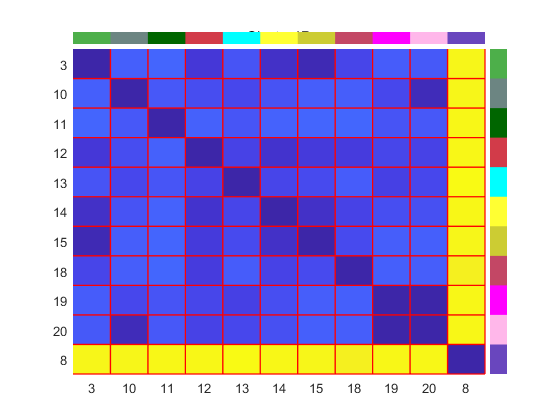

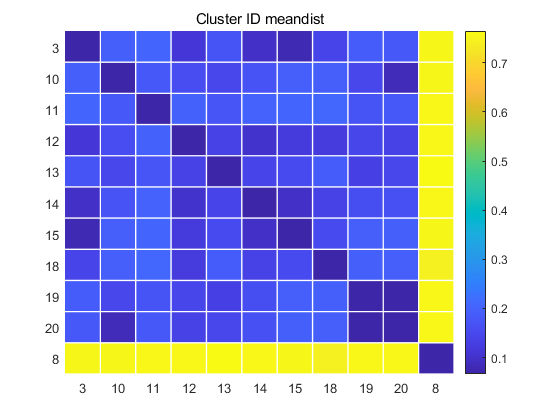

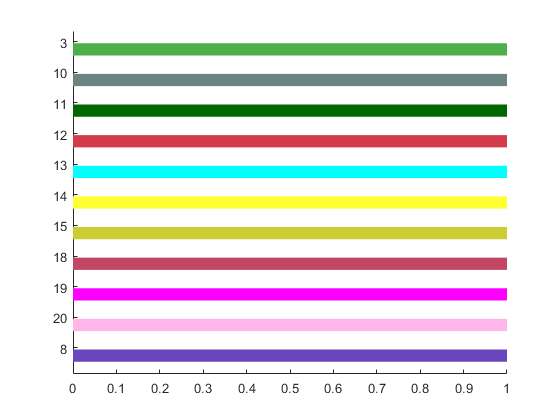

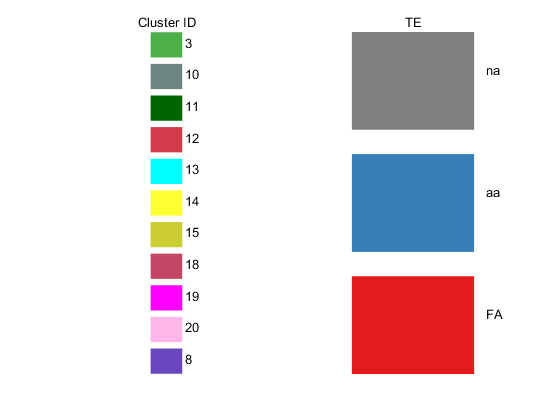

ans =     11    11


ans =     11     1


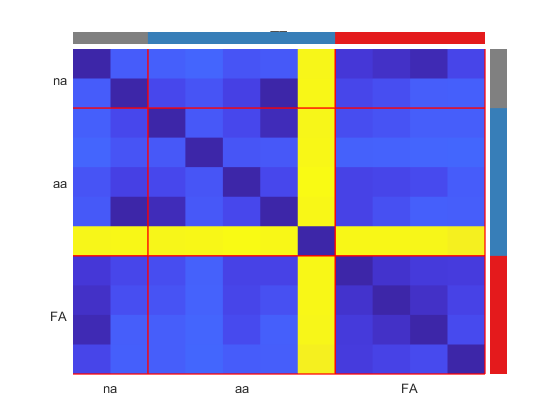

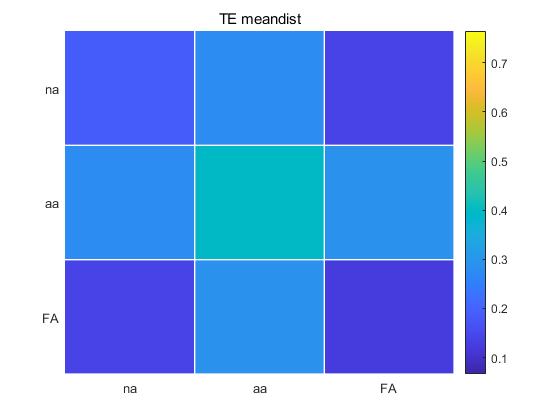

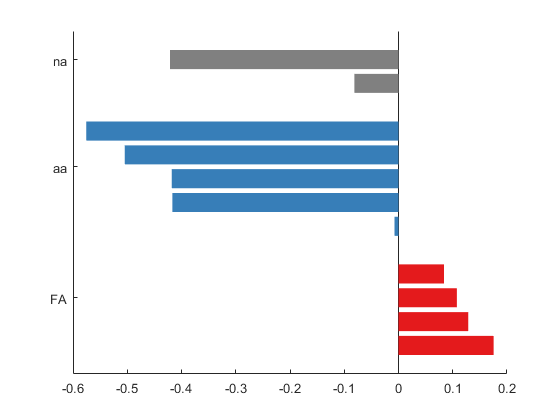

g1.id_2_color(find(strcmp(g1.id_2_name,nastr)),:)=0.5*[1,1,1];
g1.name='TE';

g2=[];
g2.ids=cEK_omains.region_ids(second_olist);
g2.id_2_name=strsplit(num2str(1:cEK_regions.num));
g2.id_2_color=cEK_regions.cluster_colors;
g2.name='Cluster ID';



groups={g2,g1};
figure;
[fhandles,optleafOrder,ai_bi_index]=DistMatrix_Analysis_HRL(dist_TE,{'phytree_complete','Silhouette'},groups);

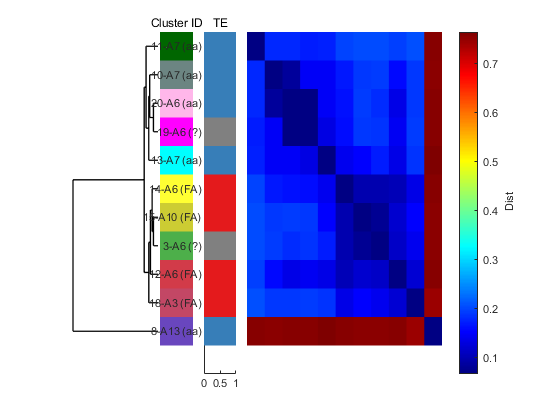


figure(fhandles(1))
axis on
set(gca,'ytick',0.5+(1:length(second_olist)));
colormap('jet')

ylabelstrs=[];
for i=1:length(optleafOrder)
    oid=second_olist(optleafOrder(i));
    rid=cEK_omains.region_ids(oid);
    
    actuals=TE_cyctype{rid};
    if strcmp(actuals,'na')
        actuals='?';
    end
    sstr=sprintf('%d-A%d (%s)',rid,cEK_omains.moduleid(oid), actuals);
    ylabelstrs{length(optleafOrder)+1-i}=sstr;
end
set(gca,'yticklabel',ylabelstrs);

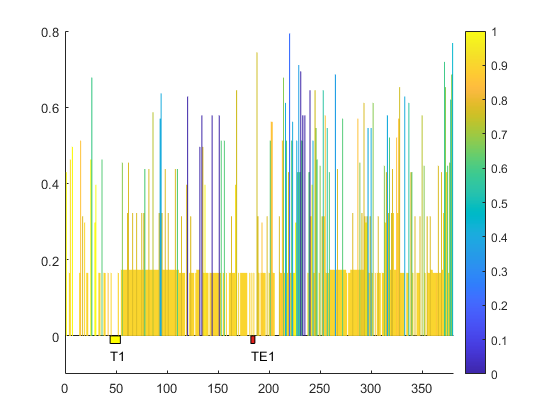




%
figure;
hold on;
% assign color
mulinfor_eachsite=TE_motifid_mdist_mul_gap(3,column_to_keep)./H2;
colortable=flipud(colormap('parula'));
colornum=size(colortable,1);
mulinfor_colorid=max(1,min(colornum,round(colornum*(mulinfor_eachsite-0)/(1))));

for i=1:length(column_to_keep)
    posi=column_to_keep(i);
    bh=bar(i,TE_motifid_mdist_mul_gap(2,posi),1);
    bh.EdgeColor='none';
    bh.FaceColor=colortable(mulinfor_colorid(i),:);
end
colorbar

% mark positions for motifs
for i=1:size(TE_combined_types,1)
    mtype=TE_combined_types(i,:);
    if abs(mtype(2)-round(mtype(2)))<0.1
        locs=find(TE_motifid_mdist_mul_gap(1,column_to_keep)==i);
        
        
         colorcode=cEK_omains.colorcode(mtype(1),:);
             
         textstr=[cEK_omains.domaintypelist{mtype(1)},num2str(mtype(2))];
       
        ph=patch([locs(1),locs(end),locs(end),locs(1)],[0,0,-1,-1]*0.02,colorcode);
        ph.EdgeColor='k';
        text((locs(1)),-0.05,textstr)
        
    end
end
ylim([-0.1,0.8]);
set(gca,'ytick',0:0.2:1)

%

highinforsite=find(mulinfor_eachsite>0.8);

% find the high-information site:
[~,order]=sort(mat_specificity);
TE_tot_msa(order,column_to_keep(highinforsite))

ans = 11×9 char 数组
    'ILDEPALSH'
    'ILDEPALSH'
    'ILDEPALSH'
    'ILDEPALSN'
    'AFHQQFPLR'
    'AFHQQFPLR'
    'AFHQQSPLR'
    'GFHQQFPLR'
    'AFRLRLGPK'
    'ILDEPALSH'
    'GFHQQVPLR'


TE_cyctype(cEK_omains.region_ids(second_olist(order)),:)

ans = 11×2 cell 数组
    {'FA'}    {'6Y'   }
    {'FA'}    {'6W'   }
    {'FA'}    {'10P'  }
    {'FA'}    {'3R'   }
    {'aa'}    {'T-7S' }
    {'aa'}    {'S-7G' }
    {'aa'}    {'T-7V' }
    {'aa'}    {'T-6I' }
    {'aa'}    {'T-13V'}
    {'na'}    {'na'   }
    {'na'}    {'?'    }


cEK_omains.region_ids(second_olist(order))

ans =     12
    14
    15
    18
    10
    11
    13
    20
     8
     3


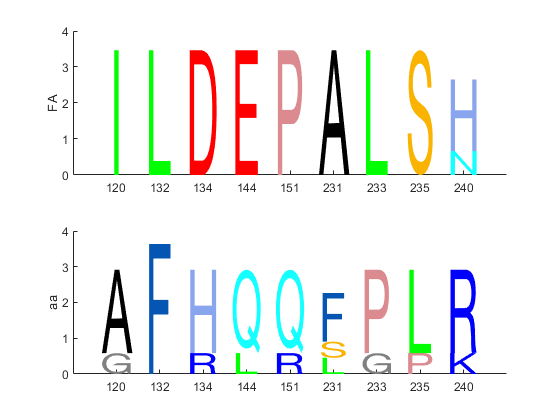

figure;
for i=1:max(mat_specificity)
    subplot(max(mat_specificity),1,i);
    thisrow=find(mat_specificity==i);
    tousestr=TE_tot_msa(thisrow,column_to_keep(highinforsite));
    
        tousestr=[tousestr;
            tousestr;
            tousestr;
            tousestr];
    
    SeqLogo_HRL(tousestr,'aa',aa_colormaping,letterclass,0);
    set(gca,'xtick',1:length(highinforsite));
    set(gca,'xticklabel',strsplit(num2str(highinforsite)));
    ylabel(TE_unifstr{i});
end

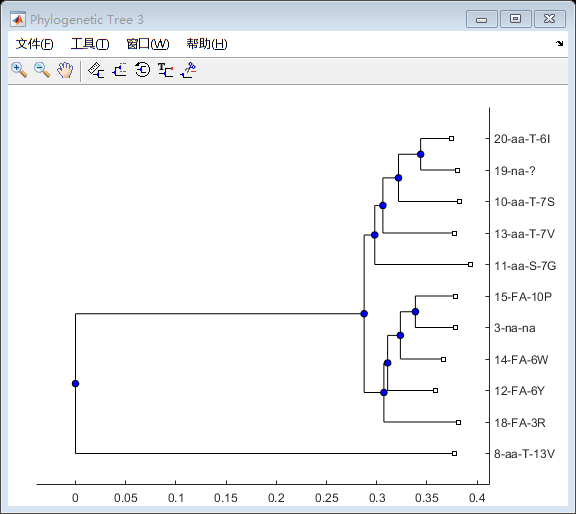



% and how it clusters
TEnames=[];
for i=1:length(second_olist)
    cid=cEK_omains.region_ids(second_olist(i));
    TEnames{i}=[num2str(cid),'-',TE_cyctype{cid,1},'-',TE_cyctype{cid,2}];
end
TEphytree = seqneighjoin(dist_TE,'equivar',TEnames);
view(TEphytree)